## 6.2. Haciendo uso del modelo directo haga una representación del espacio de trabajo alcanzable del robot.


clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.101;
L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 70]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);
bob = SerialLink(Robot_ABB,'name','bob');


N=15;
theta = linspace(pi/2,3*pi/2,N);
theta2 = linspace(0+deg2rad(10),pi+deg2rad(10),N);

figure(1);
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 -1.5 1.5]);
Robot_ABB.plot([0 0 0 0 0 0],'lightpos',[2 1 1])
Robot_ABB.teach([0 0 0 0 0 0])
hold on

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Espacio de trabajo');


for i=1:length(theta)
    for j = 1:length(theta2)
        TR=Robot_ABB.fkine([theta(i) theta2(j) -pi/2 0 0 0]);
        SURF1(i+1,j+1,:)=TR(:,4);
    end
end

surf(SURF1(:,:,1),SURF1(:,:,2),SURF1(:,:,3))
hold off




F=15;
theta3 = linspace(pi/2+deg2rad(11),3*pi/2+deg2rad(11),F);
theta4 = linspace(0,pi,F);


figure(2);
hold on;
trplot(eye(4), 'width',2,'arrow');
axis([-1 1 -1 1 -1.5 1.5]);
Robot_ABB.plot([0 0 0 0 0 0],'lightpos',[2 1 1])
Robot_ABB.teach([0 0 0 0 0 0])
hold on

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Espacio de trabajo');


for i=1:length(theta3)
    for j = 1:length(theta4)
        TR=Robot_ABB.fkine([theta4(j) theta3(i) -pi/2 0 0 0]);
        SURF1(i+1,j+1,:)=TR(:,4);
    end
end

surf(SURF1(:,:,1),SURF1(:,:,2),SURF1(:,:,3))
hold on



## 6.3. Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

Calibracion del robot respecto los puntos:

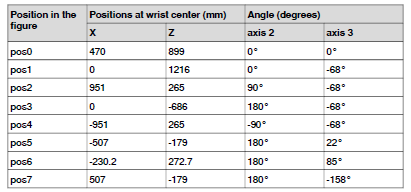

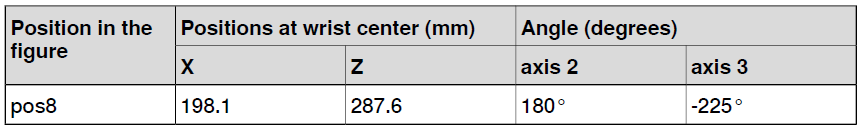

clear all; close all;
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
%q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
%Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.0;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
%plot_options = {'workspace',[-2 2 -2 2 -2 2],'scale',0.05, 'view',[140 20]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000');
%figure()
Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

T_01=L(1).A(theta_1);
T_12=L(2).A(theta_2);
T_23=L(3).A(theta_3);
T_34=L(4).A(theta_4);
T_45=L(5).A(theta_5);
T_56=L(6).A(theta_6);
digits(4);
T_FF = T_01*T_12*T_23*T_34*T_45*T_56;
%vga(T_FF);
%vga(subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[]))

Para la posición 0:

digits(4)
TR0= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 0 0 0 0 0]);
P0 = TR0(:,4);
x0 = vpa(P0(1))
z0 = vpa(P0(3))

Para la posición 1:

TR1= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 0 -deg2rad(68) 0 0 0]);
P1 = TR1(:,4); vga()
x1 = vpa(P1(1))
z1 = vpa(P1(3))

Para la posición 2:

TR2= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi/2 -deg2rad(68) 0 0 0]);
P2 = TR2(:,4);
x2 = vpa(P2(1))
z2 = vpa(P2(3))

Para la posición 3:

TR3= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi -deg2rad(68) 0 0 0]);
P3 = TR3(:,4);
x3 = vpa(P3(1))
z3 = vpa(P3(3))

Para la posición 4:

TR4= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 -pi/2 -deg2rad(68) 0 0 0]);
P4 = TR4(:,4);
x4 = vpa(P4(1))
z4 = vpa(P4(3))

Para la posición 5:

TR5= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi deg2rad(22) 0 0 0]);
P5 = TR5(:,4);
x5 = vpa(P5(1))
z5 = vpa(P5(3))

Para la posición 6:

TR6= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi deg2rad(85) 0 0 0]);
P6 = TR6(:,4);
x6 = vpa(P6(1))
z6 = vpa(P6(3))

Para la posición 7:

TR7= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi -deg2rad(158) 0 0 0]);
P7 = TR7(:,4);
x7 = vpa(P7(1))
z7 = vpa(P7(3))

Para la posición 8:

TR8= subs(T_FF,[theta_1,theta_2,theta_3,theta_4,theta_5,theta_6],[0 pi -deg2rad(225) 0 0 0]);
P8 = TR8(:,4);
x8 = vpa(P8(1))
z8 = vpa(P8(3))

## 6.4. Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores.

## Cinemática de PeterCorke (RVC)

clear all; close all;
q1=0; q2=0; q3=0; q4=0; q5=0; q6=0;
Q=[q1,q2,q3,q4,q5,q6];
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.0;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);

plot_options = {'workspace',[-10 10 -10 10 -10 10],'scale',0.05, 'view',[45 70]};
Robot_ABB = SerialLink(L,'name','ABB CRB 15000','plotopt',plot_options);



(En metros)

Para la posición 0:


TR0=Robot_ABB.fkine([0 0 0 0 0 0]);
P0 = TR0(:,4);
x0 = P0(1)
z0 = P0(3)

Para la posición 1:


TR1=Robot_ABB.fkine([0 0 -deg2rad(68) 0 0 0]); 
P1 = TR1(:,4);
x1 = P1(1)
z1 = P1(3)

Para la posición 2:


TR2=Robot_ABB.fkine([0 pi/2 -deg2rad(68) 0 0 0]); %-deg2rad(68)
P2 = TR2(:,4);
x2 = P2(1)
z2 = P2(3)

Para la posición 3:


TR3=Robot_ABB.fkine([0 pi -deg2rad(68) 0 0 0]); %-deg2rad(68)
P3 = TR3(:,4);
x3 = P3(1)
z3 = P3(3)

Para la posición 4:


TR4=Robot_ABB.fkine([0 -pi/2 -deg2rad(68) 0 0 0]); %-deg2rad(68)
P4 = TR4(:,4);
x4 = P4(1)
z4 = P4(3)

Para la posición 5:


TR5=Robot_ABB.fkine([0 pi deg2rad(22) 0 0 0]); %-deg2rad(68)
P5 = TR5(:,4);
x5 = P5(1)
z5 = P5(3)

Para la posición 6:


TR6=Robot_ABB.fkine([0 pi deg2rad(85) 0 0 0]); %-deg2rad(68)
P6 = TR6(:,4);
x6 = P6(1)
z6 = P6(3)

Para la posición 7:


TR7=Robot_ABB.fkine([0 pi -deg2rad(158) 0 0 0]); %-deg2rad(68)
P7 = TR7(:,4);
x7 = P7(1)
z7 = P7(3)

Para la posición 8:


TR8=Robot_ABB.fkine([0 pi -deg2rad(225) 0 0 0]); %-deg2rad(68)
P8 = TR8(:,4);
x8 = P8(1)
z8 = P8(3)

## Metodo por RST

clear all; close all;
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.0;
mdhparams = [0   0   	L1   	0;
            0	-pi/2   0       0;
            L2	0   	0   	0;
            L3  -pi/2	L4   	0;
            0   pi/2	0   	0;
            L5  -pi/2   L6      0];
robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,mdhparams(1,:),'mdh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,mdhparams(2,:),'mdh');
setFixedTransform(jnt3,mdhparams(3,:),'mdh');
setFixedTransform(jnt4,mdhparams(4,:),'mdh');
setFixedTransform(jnt5,mdhparams(5,:),'mdh');
setFixedTransform(jnt6,mdhparams(6,:),'mdh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

showdetails(robot)
config0=homeConfiguration(robot);
config0(2).JointPosition = -pi/2;
show(robot,config0);
axis([-1,1,-1,1,-1,1])

Para la posición 0:

config0 = homeConfiguration(robot);
Q0 = [0 0 0 0 0 0];
config0(1).JointPosition = Q0(1);
config0(2).JointPosition = Q0(2)-pi/2;
config0(3).JointPosition = Q0(3);
config0(4).JointPosition = Q0(4);
config0(5).JointPosition = Q0(5);
config0(6).JointPosition = Q0(6);
pose0 = getTransform(robot,config0,'body6')
P0 = pose0(:,4);
x0 = P0(1)
z0 = P0(3)

Para la posición 1:

config1 = homeConfiguration(robot);
Q1 = [0 0 -deg2rad(68) 0 0 0];
config1(1).JointPosition = Q1(1);
config1(2).JointPosition = Q1(2)-pi/2;
config1(3).JointPosition = Q1(3);
config1(4).JointPosition = Q1(4);
config1(5).JointPosition = Q1(5);
config1(6).JointPosition = Q1(6);
pose1 = getTransform(robot,config1,'body6');
P1 = pose1(:,4);
x1 = P1(1)
z1 = P1(3)

Para la posición 2:

config2 = homeConfiguration(robot);
Q2 = [0 pi/2 -deg2rad(68) 0 0 0];
config2(1).JointPosition = Q2(1);
config2(2).JointPosition = Q2(2)-pi/2;
config2(3).JointPosition = Q2(3);
config2(4).JointPosition = Q2(4);
config2(5).JointPosition = Q2(5);
config2(6).JointPosition = Q2(6);
pose2 = getTransform(robot,config2,'body6');
P2 = pose2(:,4);
x2 = P2(1)
z2 = P2(3)

Para la posición 3:

config3 = homeConfiguration(robot);
Q3 = [0 pi -deg2rad(68) 0 0 0];
config3(1).JointPosition = Q3(1);
config3(2).JointPosition = Q3(2)-pi/2;
config3(3).JointPosition = Q3(3);
config3(4).JointPosition = Q3(4);
config3(5).JointPosition = Q3(5);
config3(6).JointPosition = Q3(6);
pose3 = getTransform(robot,config3,'body6');
P3 = pose3(:,4);
x3 = P3(1)
z3 = P3(3)

Para la posición 4:

config4 = homeConfiguration(robot);
Q4 = [0 -pi/2 -deg2rad(68) 0 0 0];
config4(1).JointPosition = Q4(1);
config4(2).JointPosition = Q4(2)-pi/2;
config4(3).JointPosition = Q4(3);
config4(4).JointPosition = Q4(4);
config4(5).JointPosition = Q4(5);
config4(6).JointPosition = Q4(6);
pose4 = getTransform(robot,config4,'body6');
P4 = pose4(:,4);
x4 = P4(1)
z4 = P4(3)

Para la posición 5:

config5 = homeConfiguration(robot);
Q5 = [0 pi deg2rad(22) 0 0 0];
config5(1).JointPosition = Q5(1);
config5(2).JointPosition = Q5(2)-pi/2;
config5(3).JointPosition = Q5(3);
config5(4).JointPosition = Q5(4);
config5(5).JointPosition = Q5(5);
config5(6).JointPosition = Q5(6);
pose5 = getTransform(robot,config5,'body6');
P5 = pose5(:,4);
x5 = P5(1)
z5 = P5(3)

Para la posición 6:

config6 = homeConfiguration(robot);
Q6 = [0 pi deg2rad(85) 0 0 0];
config6(1).JointPosition = Q6(1);
config6(2).JointPosition = Q6(2)-pi/2;
config6(3).JointPosition = Q6(3);
config6(4).JointPosition = Q6(4);
config6(5).JointPosition = Q6(5);
config6(6).JointPosition = Q6(6);
pose6 = getTransform(robot,config6,'body6');
P6 = pose6(:,4);
x6 = P6(1)
z6 = P6(3)

Para la posición 7:

config7 = homeConfiguration(robot);
Q7 = [0 pi -deg2rad(158) 0 0 0];
config7(1).JointPosition = Q7(1);
config7(2).JointPosition = Q7(2)-pi/2;
config7(3).JointPosition = Q7(3);
config7(4).JointPosition = Q7(4);
config7(5).JointPosition = Q7(5);
config7(6).JointPosition = Q7(6);
pose7 = getTransform(robot,config7,'body6');
P7 = pose7(:,4);
x7 = P7(1)
z7 = P7(3)

Para la posición 8:

config8 = homeConfiguration(robot);
Q8 = [0 pi -deg2rad(225) 0 0 0];
config8(1).JointPosition = Q8(1);
config8(2).JointPosition = Q8(2)-pi/2;
config8(3).JointPosition = Q8(3);
config8(4).JointPosition = Q8(4);
config8(5).JointPosition = Q8(5);
config8(6).JointPosition = Q8(6);
pose8 = getTransform(robot,config8,'body6');
P8 = pose8(:,4);
x8 = P8(1)
z8 = P8(3)